cd F:\ResearchMainStream\0.ResearchBySection\C.动力学模型\参数优化\参数优化实现\并行化直曲线运行综合评价\结果分析组\7维度首次计算完成0125

clc
clear
close all

% Lx1~Lx3,2992种组合，只计算了临界速度
X_vars_2992 = readNPY('myXvars_123.npy');
CriticalVel_2992 = readNPY('myCriticalVel_123.npy'); 

% Lx1~Lx3,2992种组合，首次完成了7维度评价指标计算
X_vars_272 = readNPY('Xvars_ALL.npy');
Rlt_272 = readNPY('Result_ALL.npy');

% Lx1~Lx3,2992种组合，修改代码后第二次计算，但1940处崩溃
Xvars_0126C = readNPY('Xvars_0126C.npy');
Rlt_0126C = readNPY('Result_0126C.npy');


### 由 7个维度评价指标计算模型 获得的临界速度，局部函数

Lx1_sweep = 0:0.04:0.64; 17个元素

Lx2_sweep = 0:0.04:0.60; 16个元素

17*16=272

function Plot7dimsFrom272(X_vars_272, Rlt_272)
    
    % X_vars_272 未使用

    CriticalVel_2D_csv = reshape(Rlt_272(1,:), [16, 17]); % 临界速度
    RigidSumWearNum_2D_csv  = reshape(Rlt_272(2,:), [16, 17]);  
    IRWSumWearNum_2D_csv  = reshape(Rlt_272(4,:), [16, 17]);  
    SperlingY_2D_csv   = reshape(Rlt_272(6,:), [16, 17]);
    SperlingZ_2D_csv   = reshape(Rlt_272(7,:), [16, 17]);
    
    Lx1_sweep = 0:0.04:0.64;
    Lx2_sweep = 0:0.04:0.60;

    figure();
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  % X大小: length(Lx2_sweep)-by-length(Lx1_sweep)
    Z      = CriticalVel_2D_csv * 3.6;              % 将criticalVel_m_s转置，以匹配X, Y大小
    surf(X, Y, Z);                           % 绘制三维表面
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Critical Velocity (km/h)');
    colorbar;     
    title('Lx1、Lx2 对于临界速度的影响, Lx3=0')

    figure();
    subplot(2,1,1)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = RigidSumWearNum_2D_csv ;
    surf(X, Y, Z);             
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Total Wear Number (N)');
    colorbar;     
    title('Lx1、Lx2 对于总磨耗数的影响, 刚性轮对, Lx3=0')
    
    subplot(2,1,2)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = IRWSumWearNum_2D_csv ;
    surf(X, Y, Z);             
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Total Wear Number (N)');
    colorbar;     
    title('Lx1、Lx2 对于总磨耗数的影响, 独立轮对, Lx3=0')

    figure();
    subplot(2,1,1)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep); 
    Z      = SperlingY_2D_csv;              
    surf(X, Y, Z);                          
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Sperling Y ');
    colorbar;     
    title('Lx1、Lx2 对于 Sperling Y 的影响, Lx3=0')
    
    subplot(2,1,2)
    [X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  
    Z      = SperlingZ_2D_csv   ;         
    surf(X, Y, Z);                   
    xlabel('双拉杆构架侧间距 Lx1');
    ylabel('双拉杆轴桥侧间距 Lx2');
    zlabel('Sperling Z ');
    colorbar;     
    title('Lx1、Lx2 对于 Sperling Z 的影响, Lx3=0')

end



## 根据不同仿真、测试结果，调用局部函数（7维度评价作图）

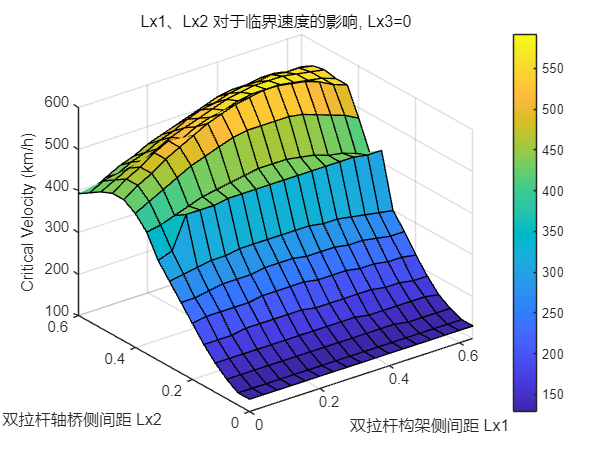

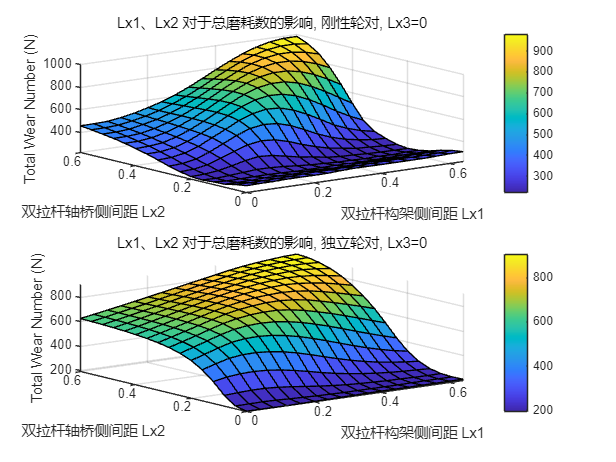

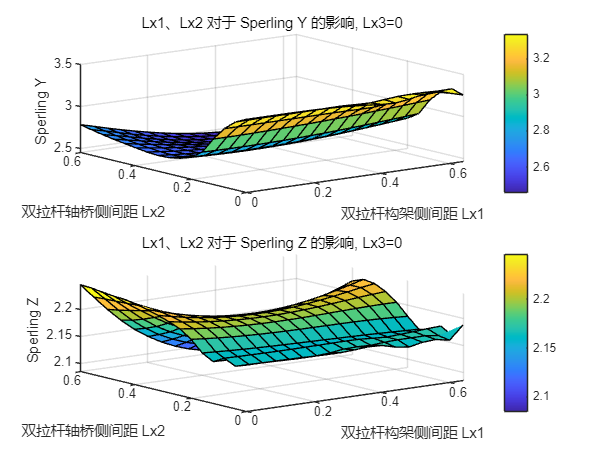

Plot7dimsFrom272(X_vars_272,Rlt_272)

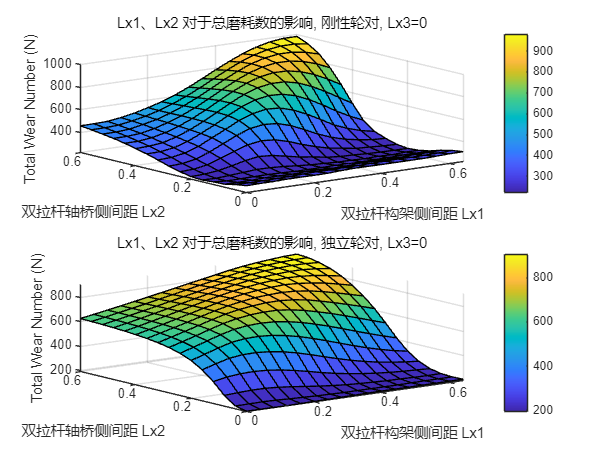

Plot7dimsFrom272(Xvars_0126C,Rlt_0126C)

### 由 2992 计算的临界速度

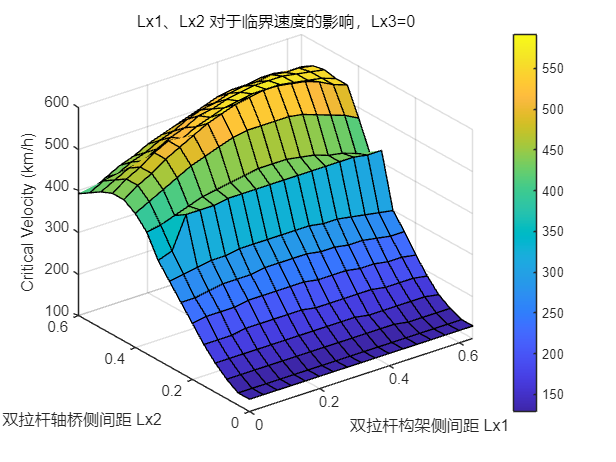

% 在 MATLAB 中重现同样的采样点
Lx1_sweep = 0 : 0.04 : 0.64;   % 17 个点
Lx2_sweep = 0 : 0.04 : 0.60;   % 16 个点
Lx3_sweep = -0.6 : 0.1 : 0.4;  % 11 个点

nLx1 = length(Lx1_sweep);  % 17
nLx2 = length(Lx2_sweep);  % 16
nLx3 = length(Lx3_sweep);  % 11

% 设置容忍度 (tol)
tol = 1e-10;

% 找到“接近0”的 Lx3 索引
index_Lx3_00 = find(abs(X_vars_2992(32, :) ) < tol); % Python数据不精确等于0
index_Lx1_06 = find(abs(X_vars_2992(30, :) - 0.6) < tol); 
index_Lx2_04 = find(abs(X_vars_2992(31, :) - 0.4) < tol); 

% 对应的 CriticalVel
CriticalVel_Lx3Eq00 = CriticalVel_2992(index_Lx3_00);
CriticalVel_Lx1Eq06 = CriticalVel_2992(index_Lx1_06);
CriticalVel_Lx2Eq04 = CriticalVel_2992(index_Lx2_04);

%% reshape 成二维矩阵进行作图

CriticalVel_2D_L1L2 = reshape(CriticalVel_Lx3Eq00, [nLx2, nLx1]);
CriticalVel_2D_L1L3 = reshape(CriticalVel_Lx2Eq04, [nLx3, nLx1]);
CriticalVel_2D_L2L3 = reshape(CriticalVel_Lx1Eq06, [nLx3, nLx2]);


% 三维可视化 - A
% {Lx1, Lx2} -> 临界速度

figure();

[X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  % X大小: length(Lx2_sweep)-by-length(Lx1_sweep)
Z      = CriticalVel_2D_L1L2 * 3.6;              % 将criticalVel_m_s转置，以匹配X, Y大小
surf(X, Y, Z);                           % 绘制三维表面
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Critical Velocity (km/h)');
colorbar;     
title('Lx1、Lx2 对于临界速度的影响，Lx3=0')


% cd F:\ResearchMainStream\0.ResearchBySection\C.动力学模型\参数优化\参数优化实现\并行化直曲线运行综合评价\ChkPnt
% 
% X_0126= readNPY('myXvars_0126C.npy');
% BR_0126 = readNPY('batch_result_0126C_batch0.npy');

cd F:\ResearchMainStream\0.ResearchBySection\C.动力学模型\参数优化\参数优化实现\并行化直曲线运行综合评价\结果分析组\0126中断至1940-from4090主机

Xvr_1940 = readNPY('myXvars_ALL25.npy');
Rlt_1940 = readNPY('final_results_merged.npy');

% 删除多余的4列
Rlt_1940(:,1940) = [];
Rlt_1940(:,1939) = [];
Rlt_1940(:,1938) = [];
Rlt_1940(:,1937) = [];

% 使用EXCEL处理，文件名：结果统计.xlsx，并保存为 L123_and_Rlt_1940
% 筛选 L3 = 0
load("L123_and_Rlt_1940.mat")
% 由此导入的变量 XnRlt_272，前三列为 Lx1, Lx2, Lx3；后 7 列为 7 维度评价指标

Xvr_272 = XnRlt_272(:,1:3);
Rlt_272 = XnRlt_272(:,4:10);

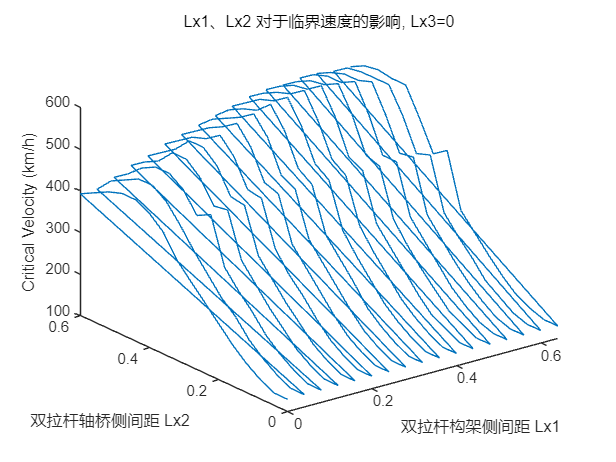

% 临界速度 三维曲线图
figure()
plot3(Xvr_272(:,1),Xvr_272(:,2),Rlt_272(:,1) * 3.6);
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Critical Velocity (km/h)');
title('Lx1、Lx2 对于临界速度的影响, Lx3=0')

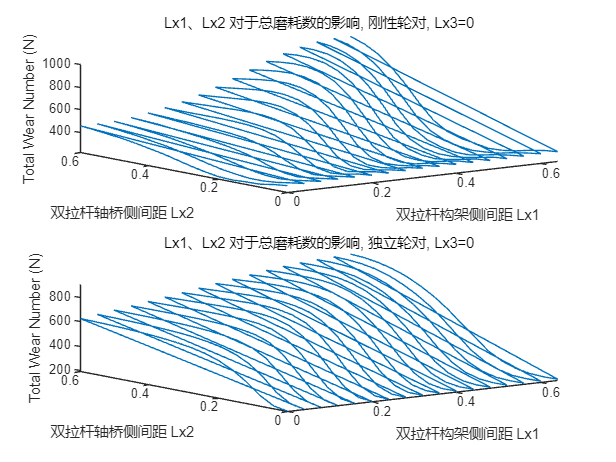


% 磨耗数 三维曲线图
figure()
subplot(2,1,1)
plot3(Xvr_272(:,1),Xvr_272(:,2),Rlt_272(:,2));
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Total Wear Number (N)');
title('Lx1、Lx2 对于总磨耗数的影响, 刚性轮对, Lx3=0')
subplot(2,1,2)
plot3(Xvr_272(:,1),Xvr_272(:,2),Rlt_272(:,4));
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Total Wear Number (N)');
title('Lx1、Lx2 对于总磨耗数的影响, 独立轮对, Lx3=0')

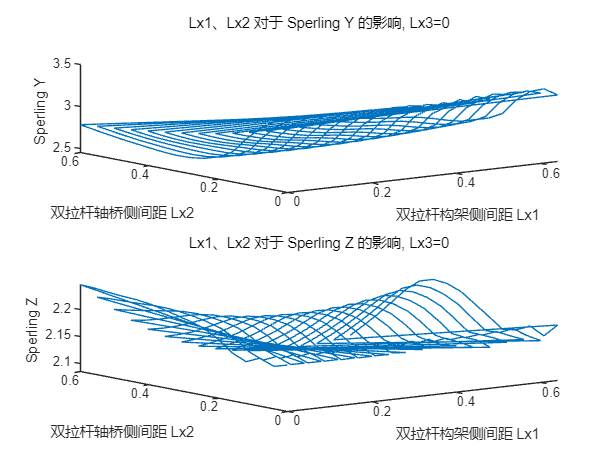


% Sperling指标 三维曲线图
figure()
subplot(2,1,1)
plot3(Xvr_272(:,1),Xvr_272(:,2),Rlt_272(:,6));
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Sperling Y ');
title('Lx1、Lx2 对于 Sperling Y 的影响, Lx3=0')
subplot(2,1,2)
plot3(Xvr_272(:,1),Xvr_272(:,2),Rlt_272(:,7));
xlabel('双拉杆构架侧间距 Lx1');
ylabel('双拉杆轴桥侧间距 Lx2');
zlabel('Sperling Z ');
title('Lx1、Lx2 对于 Sperling Z 的影响, Lx3=0')